# Aplicación de métodos numéricos a un modelo SIR

**Supuestos: **

población cerrada (no llegan personas de otros lugares) y constante ($N = S + I + R = constante$), población uniforme, mezcla homogénea (sin consideraciones de edad, distribución espacial, educación o estructura social).

Donde, $s$ es el porcentaje de personas susceptibles (pueden contraer la enfermedad), $i$ es el porcentaje de personas infectadas y $r$ es el porcentaje de personas recuperadas (y que no vuelven a contraer la enfermedad, es decir, quedan inmunes).

$\beta$ es la tasa de transmisión y $\gamma$ es la tasa de recuperación.

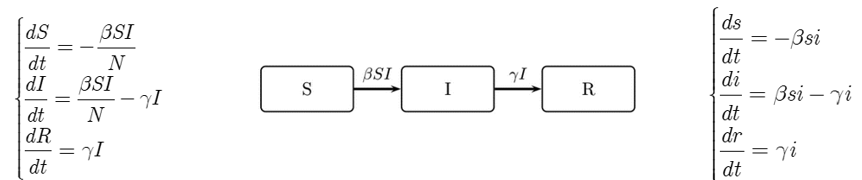

## 1. Solución numérica del modelo sin pico epidémico

syms s(t) i(t) r(t)
%Parametros
beta = 0.1; gamma = 0.2;                
%Ecuaciones del modelo SIR
f1 = -beta*s*i;                         %Susceptibles
f2 = beta*s*i - gamma*i;                %Infectados
f3 = gamma*i;                           %Recuperados            
f = odeFunction([f1 f2 f3],[s i r]);
%Para metodo numerico
h = 0.1;                                %Tamano del paso
tmin = 0;                               %Tiempo inicial 
tmax = 60;                              %Tiempo final
tspan = tmin:h:tmax;
ci = [0.9 0.1 0];                       %Condiciones iniciales
R0 = beta*ci(1)/gamma                   %Número reproductivo básico

R0 = 0.4500

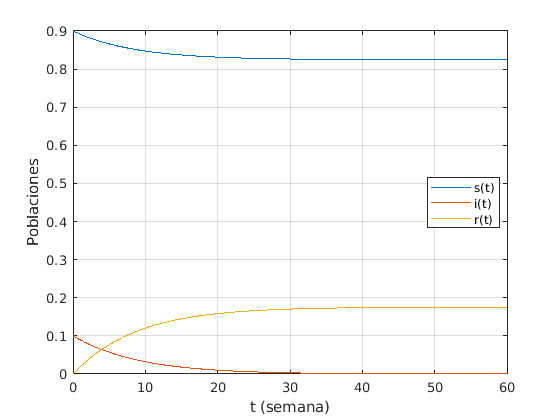

[t,x] = ode45(f,tspan,ci);
figure
plot(t,x)
xlabel('t (semana)')
ylabel('Poblaciones')
grid on 
legend({'s(t)','i(t)','r(t)'},'Location','best')

**Espacio de estado:**

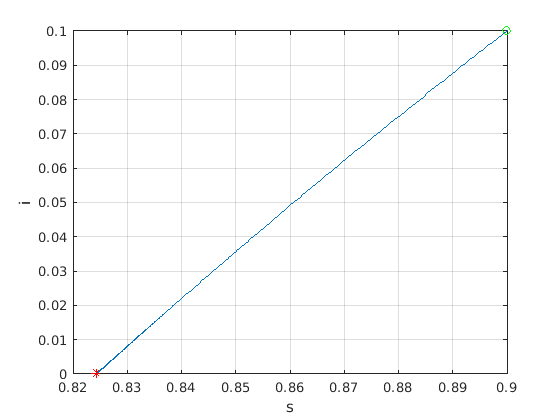

figure
plot(x(:,1),x(:,2))
hold on
plot(x(1,1),x(1,2),'og')
plot(x(end,1),x(end,2),'*r')
xlabel('s')
ylabel('i')
grid on

## 2. Solución numérica del modelo con pico epidémico

syms s(t) i(t) r(t)
beta = 0.1; gamma = 0.02;
%Ecuaciones del modelo SIR
f1 = -beta*s*i;                         %Susceptibles
f2 = beta*s*i - gamma*i;                %Infectados
f3 = gamma*i;                           %Recuperados            
f = odeFunction([f1 f2 f3],[s i r]);
%Para metodo numerico
h = 0.1;                                %Tamano del paso
tmin = 0;                               %Tiempo inicial 
tmax = 300;                             %Tiempo final
tspan = tmin:h:tmax;
ci = [0.9 0.1 0];                       %Condiciones iniciales
R0 = beta*ci(1)/gamma                   %Número reproductivo básico

R0 = 4.5000

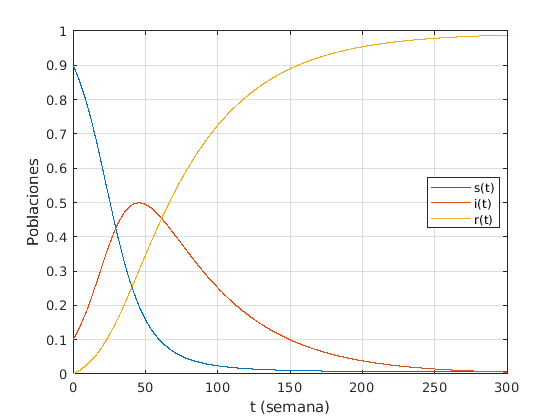

[t,x] = ode45(f,tspan,ci);
figure
plot(t,x)
xlabel('t (semana)')
ylabel('Poblaciones')
grid on 
legend({'s(t)','i(t)','r(t)'},'Location','best')

**Espacio de estado:**

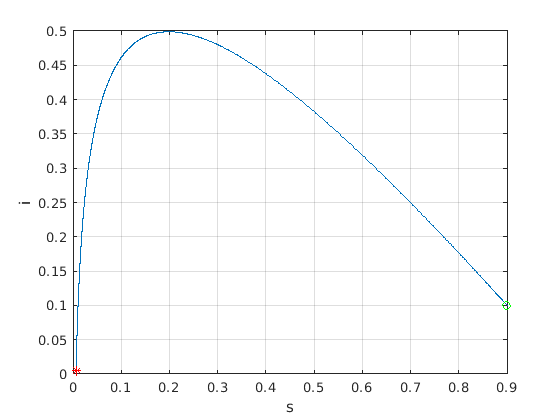

figure
plot(x(:,1),x(:,2))
hold on
plot(x(1,1),x(1,2),'og')
plot(x(end,1),x(end,2),'*r')
xlabel('s')
ylabel('i')
grid on

## 3. Soluciones numéricas con un cambio de $i(0)$

Observar el efecto negativo al tener inicialmente una población mayor de personas infectadas.

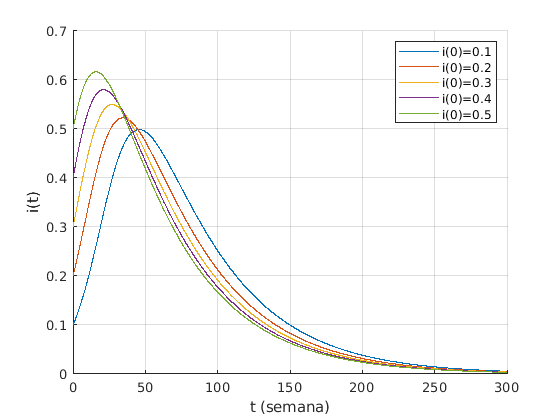

syms s(t) i(t) r(t)
%Parametros
beta = 0.1; gamma = 0.02;
%Ecuaciones del modelo SIR
f1 = -beta*s*i;                         %Susceptibles
f2 = beta*s*i - gamma*i;                %Infectados
f3 = gamma*i;                           %Recuperados            
f = odeFunction([f1 f2 f3],[s i r]);
%Para metodo numerico
h = 0.1;
tmin = 0;
tmax = 300;
tspan = tmin:h:tmax;
%Condiciones iniciales
ci = [0.9 0.1 0;
      0.8 0.2 0;
      0.7 0.3 0;
      0.6 0.4 0;
      0.5 0.5 0];

figure
for j = 1:length(ci)
    [t,x] = ode45(f,tspan,ci(j,:));
    hold on
    plot(t,x(:,2))
end
xlabel('t (semana)')
ylabel('i(t)')
grid on
legend({'i(0)=0.1','i(0)=0.2','i(0)=0.3','i(0)=0.4','i(0)=0.5'})

## 4. Soluciones numéricas con un cambio de $\beta$

Observar el efecto positivo de disminuir β (tasa de transmisión)

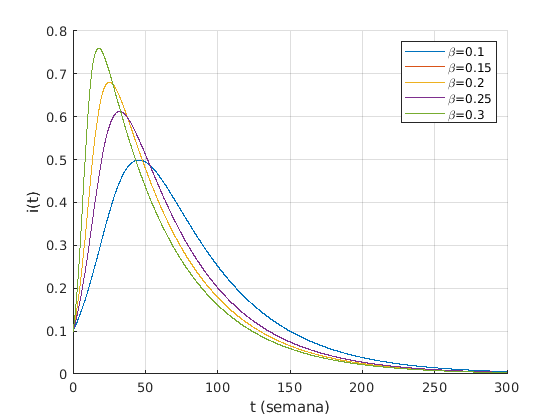

syms s(t) i(t) r(t)
%Parametro fijo
gamma = 0.02;
%Parametro que varia
beta = [0.1 0.15 0.2 0.15 0.3];
%ecuacion con parametro fijo
f3 = gamma*i;
%Para metodo numerico
h = 0.1;
tmin = 0;
tmax = 300;
tspan = tmin:h:tmax;
%condiciones iniciales
ci = [0.9 0.1 0];

figure
for beta_i = beta
    f1 = -beta_i*s*i;                             %Susceptibles
    f2 = beta_i*s*i - gamma*i;                    %Infectados     
    f = odeFunction([f1 f2 f3],[s i r]);
    [t,x] = ode45(f,tspan,ci);
    hold on
    plot(t,x(:,2))
end

xlabel('t (semana)')
ylabel('i(t)')
grid on
legend({'\beta=0.1','\beta=0.15','\beta=0.2','\beta=0.25','\beta=0.3'})

## 5. Soluciones numéricas con un cambio de $\gamma$

Observar el efecto positivo de aumentar γ (tasa de recuperación)

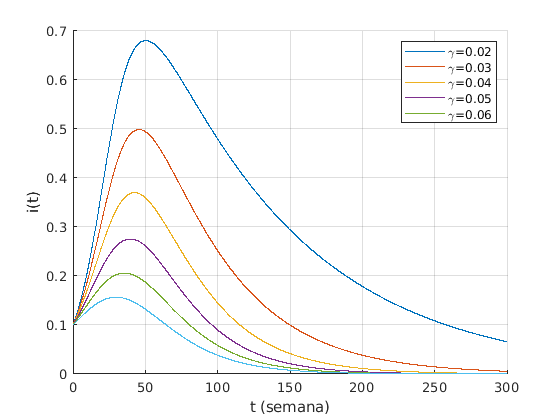

syms s(t) i(t) r(t)
%Parametro fijo
beta = 0.1;
%Parametro que varia
gamma = [0.01 0.02 0.03 0.04 0.05 0.06];
%ecuacion con parametro fijo
f1 = -beta*s*i;    
%Para metodo numerico
h = 0.1;
tmin = 0;
tmax = 300;
tspan = tmin:h:tmax;
%condiciones iniciales
ci = [0.9 0.1 0];

figure
for gamma_i = gamma
    f2 = beta*s*i - gamma_i*i;              %Infectados  
    f3 = gamma_i*i;                       %Recuperados
    f = odeFunction([f1 f2 f3],[s i r]);
    [t,x] = ode45(f,tspan,ci);
    hold on
    plot(t,x(:,2))
end

xlabel('t (semana)')
ylabel('i(t)')
grid on
legend({'\gamma=0.02','\gamma=0.03','\gamma=0.04','\gamma=0.05','\gamma=0.06'})